clear; close all;

Homework 5

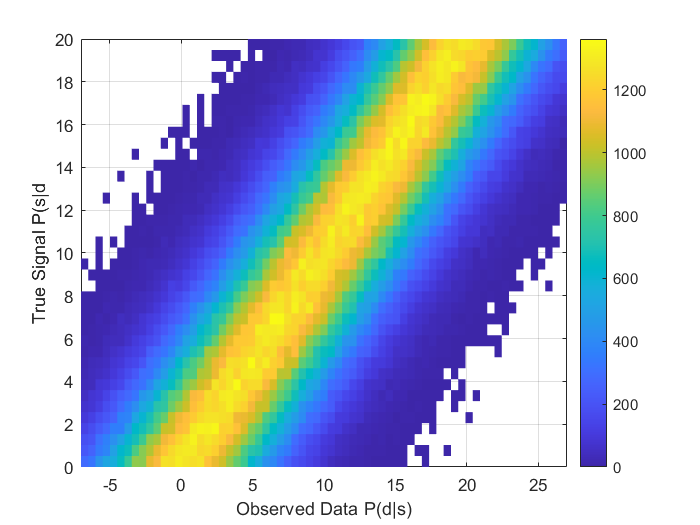

bkd = normrnd(0,4,1,1000000);
signal = unifrnd(0,20,1,1000000);
% Has to be a uniform distribution other wise there is an implicit prior

data = bkd + signal;

signaledges = linspace(0,20,40);
dataedges = linspace(-7,27,68);

H = histogram2(data,signal,'YBinEdges',signaledges,'XBinEdges',dataedges,'DisplayStyle','tile');
colorbar
xlabel('Observed Data P(d|s)')
ylabel('True Signal P(s|d')

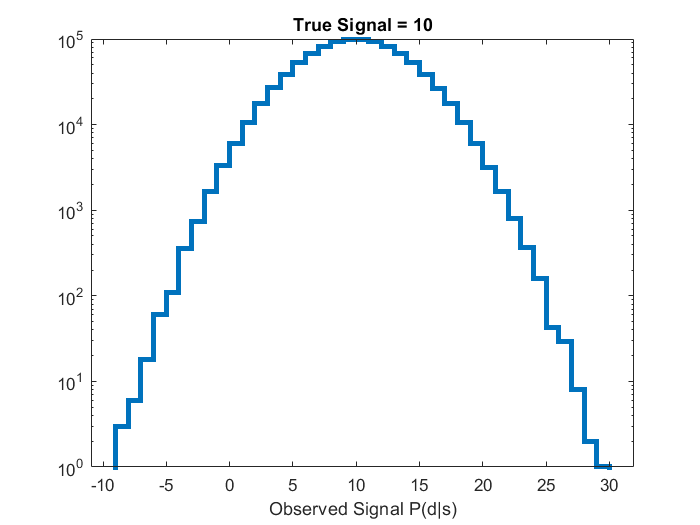


signal1 = 10;
data1 = bkd + signal1;

histogram(data1,'BinWidth',1,'DisplayStyle','stairs','LineWidth',3)
title('True Signal = 10')
xlabel('Observed Signal P(d|s)')
set(gca,'Yscale','log')

This is a horizontal slice across the 2D histogram. This graph is from a true signal of 10. The mean is 10 because the true signal is equal to 10.

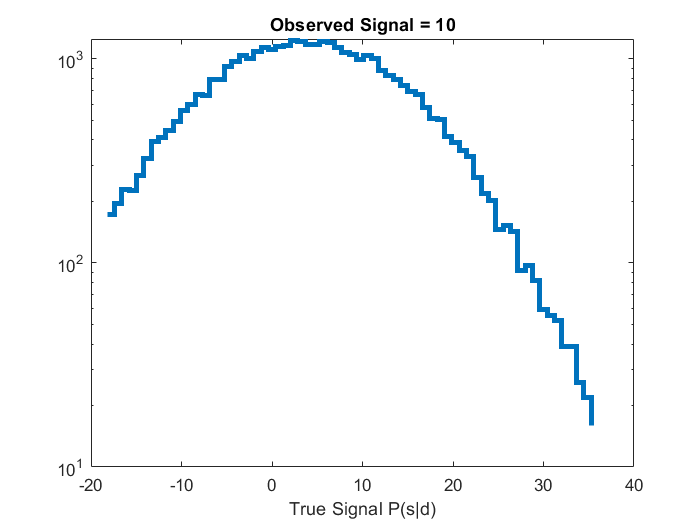

[T,B,A] = histcounts2(data,signal,67);

test = T(33,:);
stairs(B(1:end-1),test,'LineWidth',3)
title('Observed Signal = 10')
xlabel('True Signal P(s|d)')
set(gca,'Yscale','log')

This is the vertical slice across the 2D histogram. The mean is around 25. This graph is the spread of true values that could have occured at a given observed value.

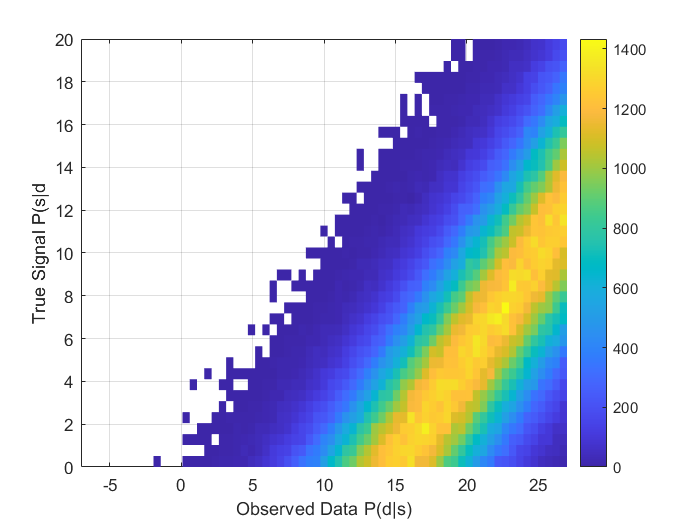

bkd = normrnd(15,4,1,1000000);
signal = unifrnd(0,20,1,1000000);
% Has to be a uniform distribution other wise there is an implicit prior

data = bkd + signal;

signaledges = linspace(0,20,40);
dataedges = linspace(-7,27,68);

H = histogram2(data,signal,'YBinEdges',signaledges,'XBinEdges',dataedges,'DisplayStyle','tile');
colorbar
xlabel('Observed Data P(d|s)')
ylabel('True Signal P(s|d')

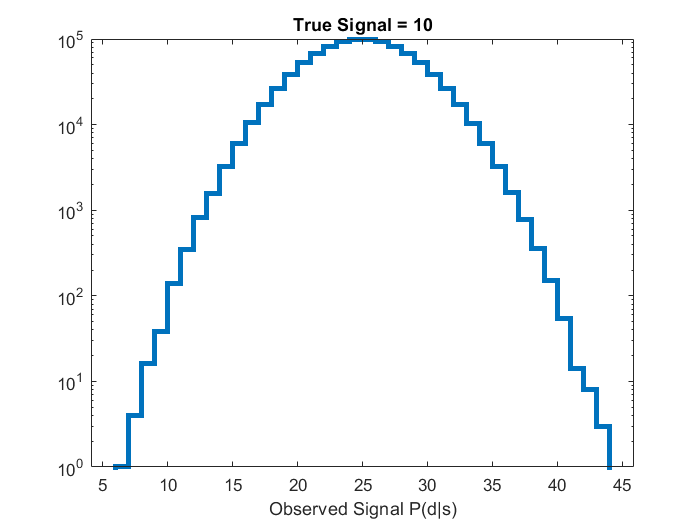

vertslice = H.Values(40,:);

signal1 = 10;
data1 = bkd + signal1;

histogram(data1,'BinWidth',1,'DisplayStyle','stairs','LineWidth',3)
title('True Signal = 10')
xlabel('Observed Signal P(d|s)')
set(gca,'Yscale','log')

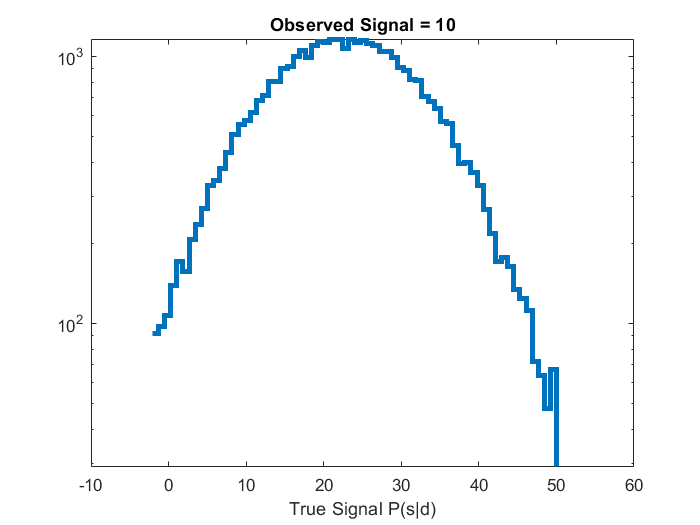


[T,B,A] = histcounts2(data,signal,67);

test = T(34,:);
stairs(B(1:end-1),test,'LineWidth',3)
title('Observed Signal = 10')
xlabel('True Signal P(s|d)')
set(gca,'Yscale','log') 

The plots are no longer centered on the same value because there is no longer a zero mean background. That means that every point in the background is a positive value and will only add to the signal not subtract from the signal.